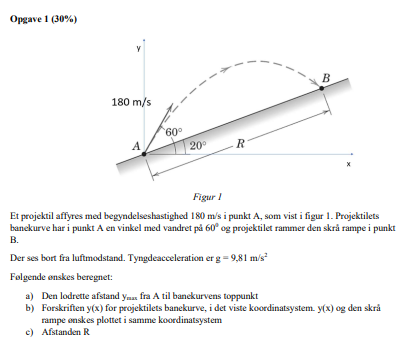

g = -9.81;
v0 = 180;
theta = deg2rad(60);
alpha = deg2rad(20)

% Hastighed i x og y
vx = v0 *cos(theta);
vy = v0 *sin(theta);

m = 1;

% Opgave a
syms y_max

U = m*g*y_max;
T = 1/2 *m*vy^2;

eq = U + T == 0;

sol = solve(eq, y_max);
y_max = vpa(sol,4)


% Opgave b

syms t Sx Sy

eqx = Sx == vx*t;

% Der løses for tiden i x-ligningen
t = solve(eqx, t)

% Tiden indsættes i stedfunktionen for y(x)
Sy = vpa(1/2*g*t^2 + vy*t, 3)

% distance i alt
eqSy = 1/2*g*t^2 + vy*t == 0;

x_pos = double(vpa(solve(eqSy, Sx),3))';


% Rampen
ramp = tan(alpha)*Sx;

% Der plottes
fplot(Sy, x_pos)

hold on
fplot(ramp, x_pos)

ylim([0, 1350]), yline(double(y_max)), grid("minor")

legend('Projektil', 'Rampe', 'y\_{max}', 'Location','best')
hold off

eq_inter = ramp == Sy;

Sx = max(solve(eq_inter, Sx))

R = Sx/cos(alpha)



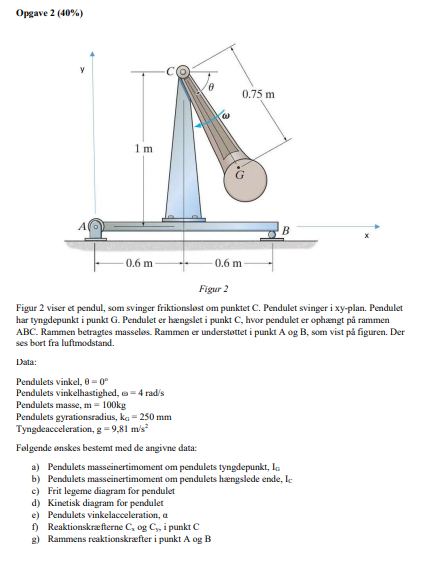

clear
% Opgave data
theta = 0;
w = 4; %rad/s
m = 100; %kg

kG = 0.250; % mm til m
rG = 0.75; 
g = 9.81;

## Opgave a) og b)

Ig = kG^2*m

Ig = 6.2500


L = 0.75;
Ic = Ig + rG^2*m

Ic = 62.5000

## Opgave c) og d)

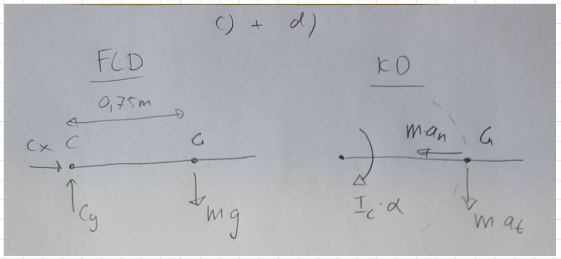

## Opgave e)

Pendulets vinkelacceleration

Vi finder vinkelacceleration ved 0 grader via energi ligningen

da vi har 


$$M_C = I_C \cdot \alpha$$



$$V_g = m \cdot g \cdot h$$



$$I_c \cdot \alpha  = mgh
\\
\alpha = \frac{mgh}{I_c}$$


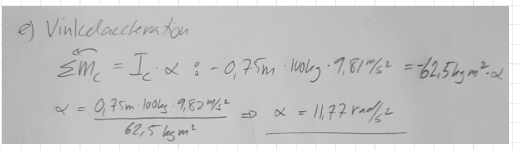

alpha = m*g*rG/Ic

alpha = 11.7720

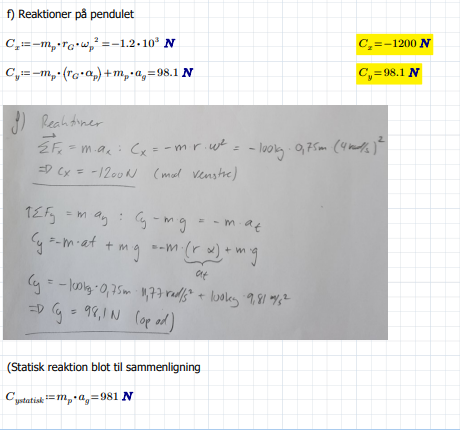

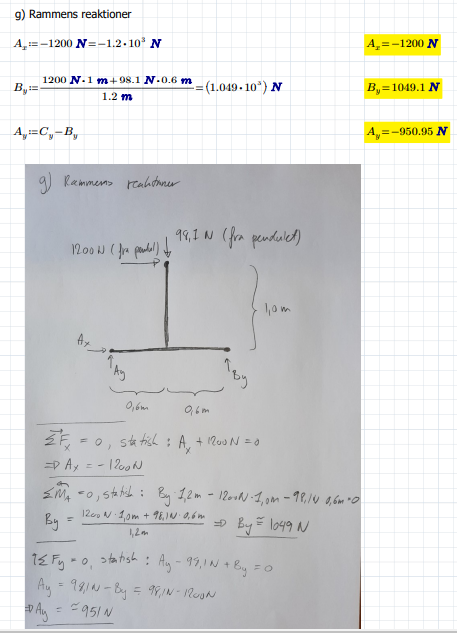

clear


# Opgave 3